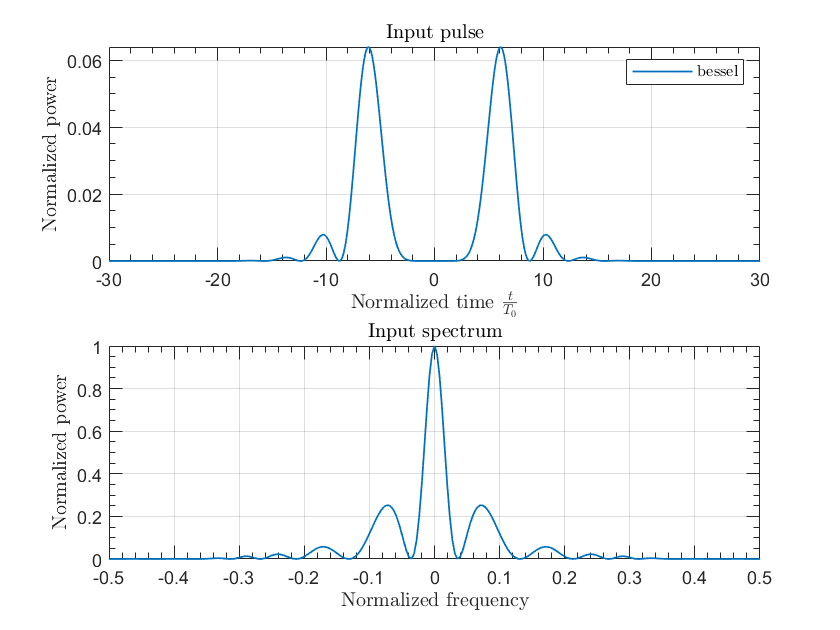

% SSFM code for solving the normalized NLS equation
%Modified version of the code provided by
%G.P. Agrawal for the 6th edition of NLFO book

fiblen = 5;     % fiber length (in units of L_D)
beta2 =-1;      % sign of GVD parameter beta_2
N = 1;          % sign of GVD parameter beta_2


%---set simulation parameters---%
nt = 2048; Tmax = 128;            %FFT points and time window size
step_num = round(20*fiblen*N^2); %No. z steps
deltaz = fiblen/step_num;        %step size in z
dtau = (2*Tmax)/nt;              %step size in tau

tns= (-nt/2:nt/2-1);             
tau = tns*dtau;                          %time array
omega = fftshift(tns)*(pi/Tmax);         %omega array
q = 5;
w0 = 10;
J = abs(besselj(q,tau));
P0 = 1;
uu = sqrt(P0)*exp((-(tau.^2)/(w0^2))).*J;         %input pulse shape
uusech = sqrt(P0)*sech(tau);
uugauss = sqrt(P0)*exp(-tau.^2);
%---plot input pulse shape and spectrum---%
temp = fftshift(ifft(uu));        %fourier transform
spect = abs(temp).^2;             %input spectrum
spect = spect./max(spect);        %normalized spectrum
freq = fftshift(omega)/(2*pi);    %frequency array

subplot(2,1,1)
plot(tau,abs(uu).^2, "LineWidth", 0.9)
legend('bessel', 'Interpreter', 'latex')
xlabel('Normalized time $\frac{t}{T_0}$', "Interpreter", "latex")
ylabel('Normalized power', 'Interpreter',"latex")
title('Input pulse', "Interpreter","latex")
xlim([-30 30])
ylim([0 max(abs(uu).^2)])
grid on
set(gca, 'XMinorTick', 'on', 'YMinorTick', 'on', ...
         'TickLength', [0.02, 0.04], ...
         'LineWidth', 0.5);

subplot(2,1,2)
plot(freq, spect, "LineWidth", 0.9)
title('Input spectrum', "Interpreter","latex")
xlabel('Normalized frequency', "Interpreter", "latex")
ylabel('Normalized power', 'Interpreter',"latex")
xlim([-.5 .5])
grid on
set(gca, 'XMinorTick', 'on', 'YMinorTick', 'on', ...
         'TickLength', [0.02, 0.04], ...
         'LineWidth', 0.5);


%---store dispersive phase shifts---%

